# **EXTRACT**: **t**ractable and **r**obust  **a**utomated **c**ell extraction **t**ool for calcium imaging

It ***extracts*** the activities of cells as time series from both one-photon and two-photon Ca2+ imaging movies

## Introduction to the EXTRACT pipeline

Steps:

- **Input raw movie:** The pipeline takes a raw 1p/2p Ca2+ imaging movie as an  input.

- **Pre-processing:** Perform motion correction using exisiting external algorithms (for example: [NoRMCorre](https://github.com/flatironinstitute/NoRMCorre)).  and various pre-processing steps. EXTRACT has a configuration to perform the usual pre-processing steps including taking dF/F, highpass filtering for suppressing excessive background, and circular masking for endoscopic movies (see Configuration details).

- **EXTRACT: **The pre-processed movie is used by the EXTRACT algorithm to perform tractable and robust cell extraction.

- **Cell sorting:** One can use either EXTRACT's internal sorter or use an external sorter for this step.

- **Output:** The output consists of temporal traces and spatial maps for future data analysis.

- **Cell checker**: EXTRACT has an internally built-in cell-check algorithm, which employs  semi-supervised machine learning methods to aid the user with the cell  checking process (see cell checker for details).

EXTRACT code in this repository provides most of the pipeline (colored as green in the figure). We also provide some links to the external repositories whenever needed (colored as orange in the figure).

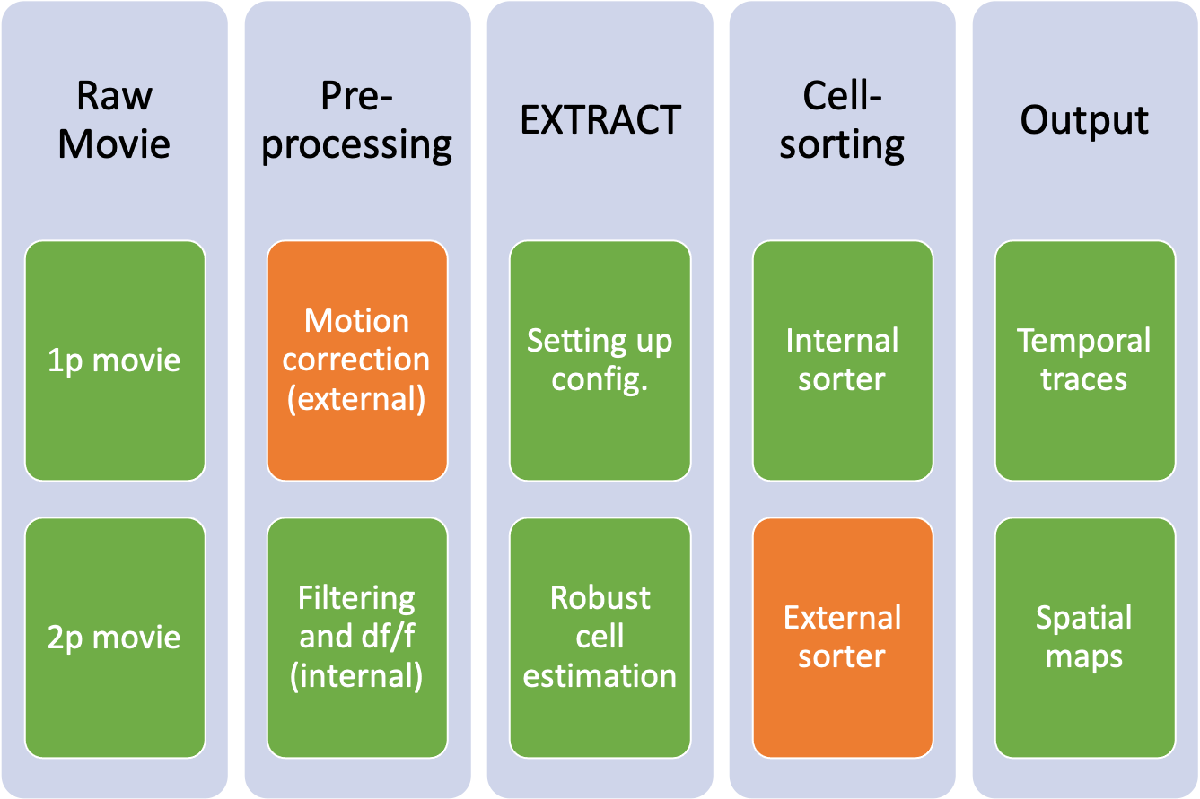

Figure credit: Schnitzer Lab

## **Dependencies**

Before running the utorial, first check that all the dependencies are installed. EXTRACT requires, at least, the following toolboxes. With future releases, there may be need for further toolboxes.

- Bioinformatics Toolbox

- Econometrics Toolbox

- Image Processing Toolbox

- Parallel Computing Toolbox

- Signal Processing Toolbox

- Statistics and Machine Learning Toolbox

- Wavelet Toolbox

## Input

It is a good practice to clear the RAM before loading the input data and performing cell extraction. In this tutorial, the input file (example.mat)

contains a movie M, ground truth spatial cell maps (S_ground), and ground truth time-series traces (T_ground).

clear;
load('example.mat'); 


## Configurations

It is essential to define the configuration to be used for running EXTRACT. To know the full list of advanced configurations and their defaults, see this: [Configurations](https://github.com/schnitzer-lab/EXTRACT-public#configurations)

### Default configurations

config = [];
config = get_defaults(config); 


### Essential configuration

It is essential to define the average cell radius, without this EXTRACT will give an error.

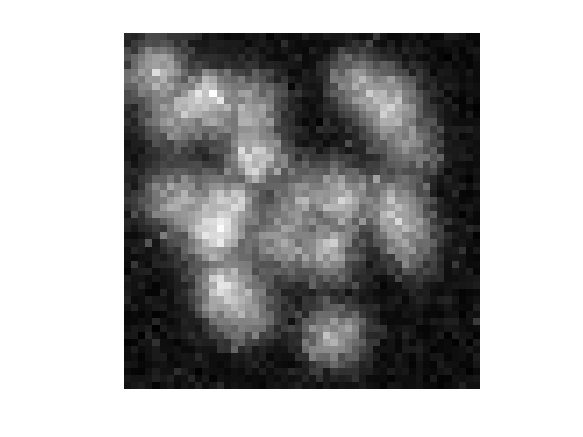


% By considering the maximum projections, pick an estimate cell radius
figure, imshow(max(M,[],3),[]);



config.avg_cell_radius = 7; % Average cell radius is 7.



### Optional configurations

While these are optional, it is strongly advised to handpick the following configurations. 

For this tutorial, the example movie is small enough that EXTRACT will not automatically partition this, but it is a good idea to keep the following in mind. Change the number of partitions for loading movies that won't fit into the RAM. 

config.num_partitions_x=1;
config.num_partitions_y=1; 

Choose the output trace option: 'nonneg' for non-negative Ca2+ traces, 'raw' for raw ones.

config.trace_output_option='raw'; 

If the movie is clean enough (as in this tutorial), there is no need to lowpass filter it. Else use of the spatial smoothing filter options for finding cells.

config.cellfind_filter_type='none';

Keeping verbose=2 gives insight into the EXTRACTion process. It is always advised to keep verbose=2.

config.verbose=2; 

no need for highpass filtering

config.spatial_highpass_cutoff=inf; 

no need for background removal

config.remove_background=0;

### Optional configurations whose defaults exist

This is a small dataset, will be fast on cpu anyways.

config.use_gpu=0; 

10 is a good number of iterations for this dataset.

config.max_iter = 10; 

Adaptive kappa is on for this movie. For an actual movie, keeping it off may be beneficial depending on the noise levels.

config.adaptive_kappa = 1;

Default snr is 1, lower this (never less than 0) to increase cell count at the expense of more spurious cells!

config.cellfind_min_snr=0.5;

### Advanced configurations

- `preprocess`: EXTRACT does preprocessing steps such as  taking dF/F, highpass filtering for suppressing excessive background,  and circular masking for endoscopic movies. Set to `false` to skip all preprocessing. Default: `true`.

- `downsample_time_by`, `downsample_space_by`: Downsampling factors. Set to `'auto'` for automatic downsampling factors based on avg cell radius and avg calcium event time constant. Defaults: `1` & `1`.

- `multi_gpu``:` Boolean flag for parralel processing of different movie partitions on multiple GPUs (if applicable) in the GPU mode. Default: `false`.

- `parallel_cpu:` Boolean flag for parallel processing of different movie partitions in the CPU mode. This flag is only effective when `use_gpu = 0`. Default: `false`.

- `num_parallel_cpu_workers``:` When `config.parallel_cpu = 1`, this parameter can be used to set the desired number of CPU workers.  Default is # of available cores to Matlab - 1 (minus 1 is for leaving  compute room for other tasks).

- `min_radius_after_downsampling`: When `downsample_space_by= 'auto'`, this determines the spatial downsampling factor by setting a minimum avg radius after downsampling. Default: `5`.

- `min_tau_after_downsampling`: When `downsample_time_by='auto'`, this determines the temporal downsampling factor by setting a minimum event tau after downsampling. Default: `5`.

- `reestimate_S_if_downsampled`: When set to `true`, images are re-estimated from full movie at the end. When `false`, images are upsampled by interpolation. `reestimate_S_if_downsampled=true` is not recommended as precise shape of cell images are typically not essential, and re-estimation from full movie is costly.

- `verbose`: Log is emitted from the console output when set to `1`, set to `0` to suppress output. When set to `2`, EXTRACT provides a detailed summary during the signal extraction process. Default: `2`.

- `crop_cicrcular`: For microendoscopic movies, set it to `true` for automatically cropping out the region outside the circular imaging region. Default: `false`.

- `dendrite_aware`: Boolean flag, set it to `true` if dendrites exist in the movie & are desired in the output. Default: `false`.

- `adaptive_kappa`: If `true`, then during cell finding, the robust esimation loss will adaptively set its robustness parameter. Default: `false`.

- `smoothing_ratio_x2y`: If the movie contains mainly  objects that are elongated in one dimension (e.g. dendrites), this  parameter is useful for more smoothing in either x or y dimension.  Default: `1`.

- `compact_output`: If set to `true`, then the  output will not include bad components that were found but then  eliminated. This usually reduces the memory used by the output struct  substantially. Default: `true`.

- `use_sparse_arrays`: If set to `true`, then the output cell images will be saved as sparse arrays. Default: `true`.

- `temporal_denoising`: Boolean flag that determines  whether to apply temporal wavelet denoising. This functionality is  experimental; expect it to increase runtime considerably if the input  movie has >10K frames and hase larger field of view than 250x250  pixels. Default: `false`.

- `remove_background`. Boolean flag that determines whether to subtract the (spatially) background (largest spatiotemporal mode of  the movie matrix). Default: `true`.

- `cellfind_max_steps`: Maximum number of cell candidate initialization during cell finding step. Default: `1000`.

- `cellfind_kappa_std_ratio`: Kappa will be set to this times the noise std for the component-wise EXTRACT during initialization. Default: `1`.

- `cellfind_filter_type`: Type of the spatial smoothing filter used for cell finding. Options: `'butter'` (IIR butterworth filter), `'gauss'` (FIR filter with a gaussian kernel), `'wiener'` (wiener filter), `'movavg'` (moving average in space), `'none'` (no filtering). Default: `'butter'`.

- `spatial_highpass_cutoff`, `spatial_lowpass_cutoff`: These cutoffs determine the strength of butterworth spatial filtering  of the movie (higher values = more lenient filtering), and are relative  to the average cell radius. Defaults: `5` & `2`.

- `init_with_gaussian`: If true, then during cell finding,  each cell is initialized with a gaussian shape prior to robust  estimation. If false, then initialization is done with a correlation  image (preferred for movies with dendrites). Default: `false`.

- `cellfind_numpix_threshold`: During cell finding, objects with an area < `cellfind_numpix_threshold` are discarded. Default: `9`.

- `S_init`: Optionally, provide cell images in `config.S_init` as a 2-D matrix (with the size of the first dimension equal to movie  height x movie width), and the algorithm will use these as the initial  set of cells, skipping its native initialization. Default: empty array.

- `smooth_T` : If set to `true`, calculated traces are smoothed using median filtering. Default : `false`.

- `smooth_S` : If set to `true`, calculated images are smoothed using a 2-D gaussian filter. Default : `true`.

- `max_iter` : Maximum number of alternating estimation iterations. Default : `6`.

- `plot_loss`: When set to `true`, empirical risk is plotted against iterations during alternating estimation. Default: `false`.

- `l1_penalty_factor`: A numeric in range `[0, 1]` which determines the strength of l1 regularization penalty to be  applied when estimating the temporal components. The penalty is applied  only to cells that overlap in space and whose temoral components are  correlated. Use larger values if spurious cells are observed in the  vicinity of high SNR cells. Default: `0`.

- `max_iter_S`,`max_iter_T` : Maximum number of iterations for `S` and `T` estimation steps. Default: `100` and `100`.

- `TOL_sub` : If the 1-step relative change in the objective within each `T` and `S` optimization is less than this, the respective optimization is terminated. Default: `1e-6`.

- `kappa_std_ratio`. Kappa will be set to this times the  noise std during the cell refinement process. Lower values introduce  more robustness at the expense of an underestimation bias in `S` and `T` (especially in the low SNR regime). Default : `1`.

- `TOL_main` : If the relative change in the main objective function between 2 consecutive alternating minimization steps is less  than this, cell extraction is terminated. Default: `1e-6`.

- `medfilt_outlier_pixels`: Flag that determines whether outlier pixels in the movie should be replaced with their neighborhood median. Default: `false`.

- `remove_duplicate_cells`: For movies processed in multiple partitions, this flag controls duplicate removal in the overlap regions. Default: `true`.

- `T_dup_corr_thresh`,`S_dup_corr_thresh` : Through alternating estimation, cells that have higher trace correlation than `T_dup_corr_thresh` and higher image correlation than `S_dup_corr_thresh` are eliminated. Defaults: `0.95` & `0.95`.

- `temporal_corrupt_thresh` , `spatial_corrupt_thresh` : Spatial & temporal corruption indices are calculated at each step of the alternating minimization routine. Images / traces that have an  index higher than these are eliminated. Defaults : `0.7` & `0.7`.

- `T_min_snr` : Cells with lower SNR value than `T_min_snr` will be eliminated. Default: `10`.

We suggest checking out `get_defaults.m` for further info on how to set these parameters.

## Perform EXTRACTion

output=extractor(M,config);

16-Dec-2021 14:56:02: Signal extraction on partition 1 (of 1):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0203 
	 	 	 	 minimum magnitude: 0.0142 
	 	 	 19 cells found after a total of 21 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 19 (0 removed) 
	 	 	 End of iter # 2: # cells: 19 (0 removed) 
	 	 	 End of iter # 3: # cells: 19 (0 removed) 
	 	 	 End of iter # 4: # cells: 19 (0 removed) 
	 	 	 End of iter # 5: # cells: 19 (0 removed) 
	 	 	 End of iter # 6: # cells: 19 (0 removed) 
	 	 	 End of iter # 7: # cells: 19 (0 removed) 
	 	 	 End of iter # 8: # cells: 19 (0 removed) 
	 	 	 End of iter # 9: # cells: 19 (0 removed) 
	 	 	 End of iter # 10: # cells: 19 (0 removed) 
	 	 	 Providing raw traces. 
	 	 	 Count: 19 cells.
16-Dec-2021 14:56:32: T

## Matching ground truth to EXTRACTed signals

figure; imshow(output.info.summary_image)

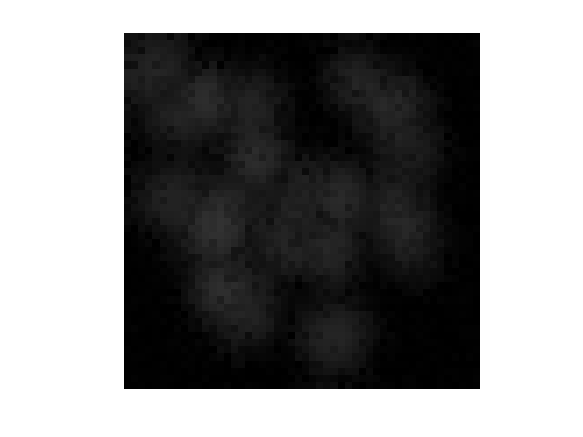

figure; imagesc(output.info.F_per_pixel)

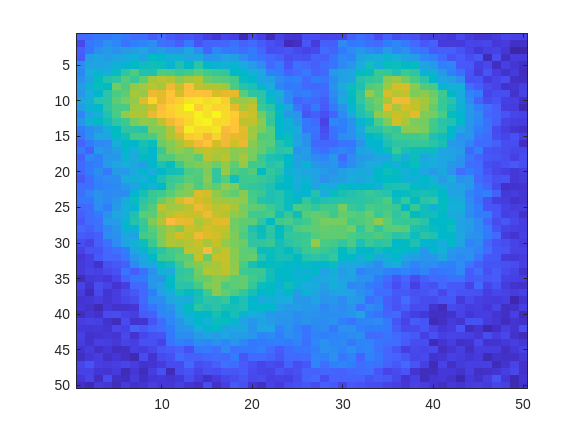

figure; imshow(output.info.max_image)

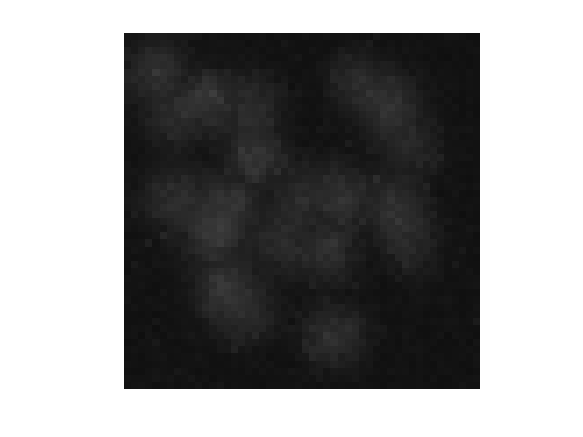

montage(output.spatial_weights)'

Pick a cell number from the 19 EXTRACTed cells and display its spatial weights. Note that as per the ground truth, there are 20 cells. 

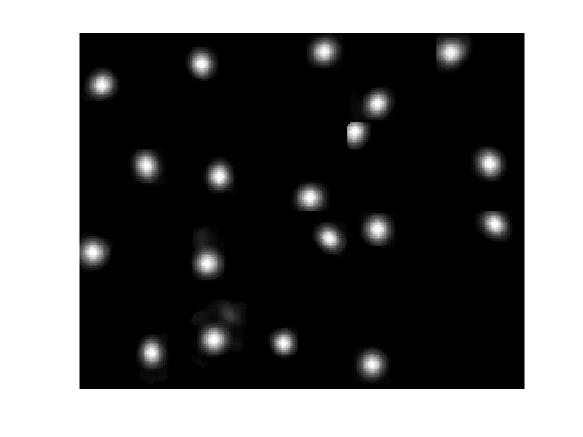

ans =   Image with properties:

           CData: [864×1080 single]
    CDataMapping: 'scaled'

  Show all properties


pick=19; 

figure;
imagesc(output.spatial_weights(:,:,pick)')

figure;
imshow(output.spatial_weights(:,:,pick)')

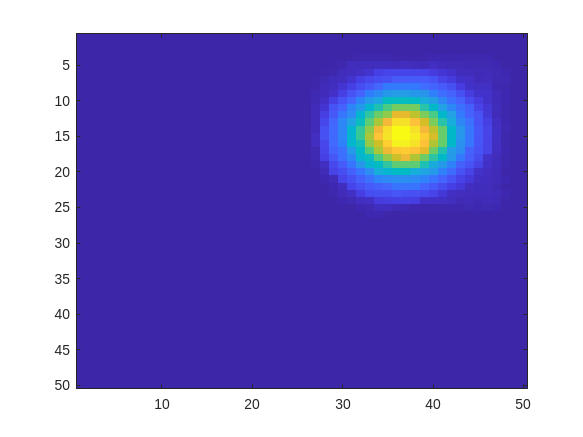

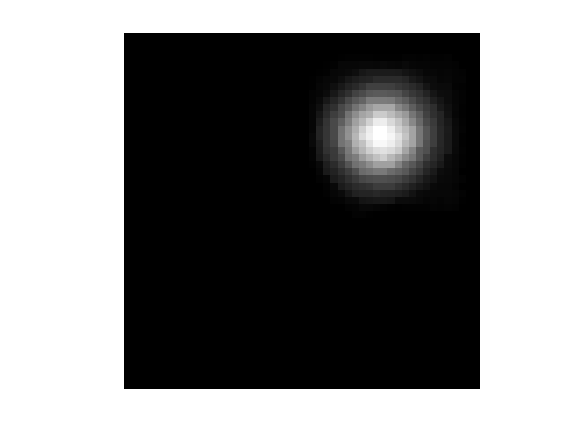

[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);
idx_match = match_sets(S_ex, S_ground); %this is a very useful helper function, use this as you need!


T_ex = output.temporal_weights';

## Perform multivariate linear regression for comparison

M_res=reshape(M,2500,2000);
X=mean(M_res,2);
M_res=(M_res-X)./X; %perform dfof
S=S_ex;
T_est=(S'*S)^(-1)*S'*M_res;
% Since this movie does not contain unfound cells or neuropils, this will
% be close to ground truth and EXTRACT outputs!


plot(T_ex(idx_match(1,pick),:));
hold on
plot(T_ground(idx_match(2,pick),:))
hold on
plot(T_est(idx_match(1,pick),:))

## Cell checker

### **Internal cell checker with semi-supervised assistance**

EXTRACT has an internally built-in cell-check algorithm,  which employs semi-supervised machine learning methods to aid the user  with the cell checking process. The corresponding file is `cell_check.m`, which takes in two inputs: `M` and `output`. `M` is the movie, whereas `output` is the output generated by EXTRACT that contains cell maps and temporal traces. It has the following properties:

- The user can observe the cell maps during spiking times or click on  the temporal trace map to watch the raw movie during that time window.

- The user can decide whether a candidate is indeed a cell or not.

- The algorithm performs some computations in the background to assist the user, where the user can decide on some acceptance and rejection  thresholds.

- Once a small portion of cell candidates are checked, the algorithm  provides a guess for all the cell candidates. Thus, one does not need to check all the cells.

The figure below explains the process in 4 steps. In this  example, the user had checked only 5 cell candidates and EXTRACT  identified 18 cells and 6 non-cells. We note that this feature is still  experimental and we are constantly working to improve it. We are also  providing an external cell checker in case cell_check fails, which  usually happens when the number of EXTRACT partitions is larger than 1.

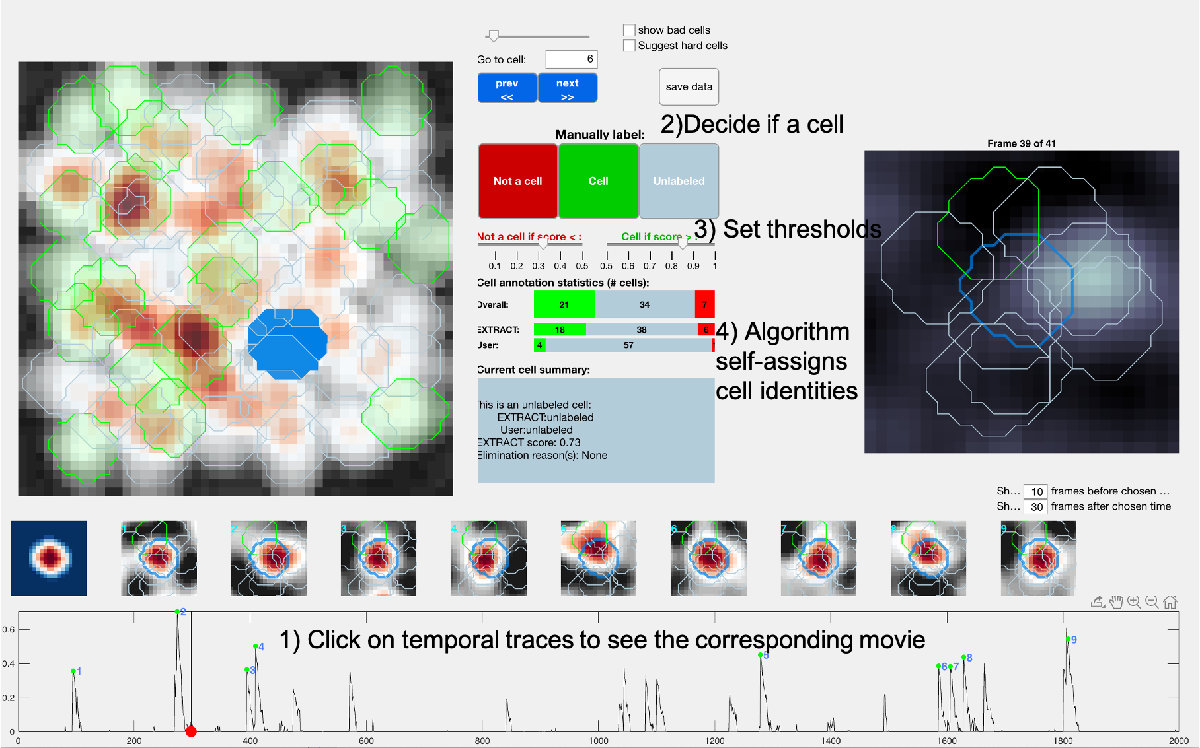

### **External cell checker**

There is also an external cell checker, which is part of the [CIAtah](https://github.com/bahanonu/calciumImagingAnalysis) pipeline. After downloading and including the pipeline in the MATLAB  path, one can use the following code to run the EXTRACT output on the  cell checker of CIAtah pipeline:

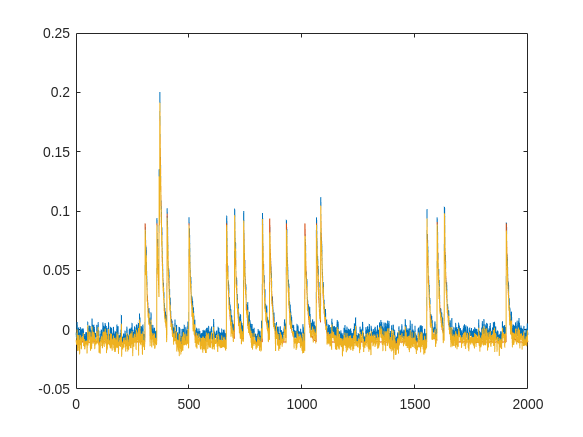

% EXTRACT output is stored in a structure called "output"

% Some configurations for the external cell checker
iopts.inputMovie = M; % movie associated with traces
iopts.valid = 'neutralStart'; % all choices start out gray or neutral to not bias user
iopts.cropSizeLength = 20; % region, in px, around a signal source for transient cut movies (subplot 2)
iopts.cropSize = 20; % see above
iopts.medianFilterTrace = 0; % whether to subtract a rolling median from trace

iopts.subtractMean = 0; % whether to subtract the trace mean
iopts.backgroundGood = [208,229,180]/255;
iopts.backgroundBad = [244,166,166]/255;
iopts.backgroundNeutral = repmat(230,[1 3])/255;

% Run the external cell checker
[inputImagesSorted, inputSignalsSorted, choices] = ciapkg.api.signalSorter(output.spatial_weights, output.temporal_weights', 'options',iopts);

## Understanding hyperparameters

clear;

Unrecognized function or variable 'M'.

M = single(hdf5read('Fig4_example.h5','/data'));

config=[];
config = get_defaults(config); %calls the defaults


% Essentials, without these EXTRACT will give an error:
config.avg_cell_radius=6; 

% The movie is large, change the partitions if needed.
config.num_partitions_x=5;
config.num_partitions_y=5; 

% All the rest is to be optimized, which is the purpose of this tutorial!

output=extractor(M,config);

%% Check quality
figure, imshow(max(M,[],3),[0 50]);
plot_cells_overlay(output.spatial_weights,[1,0,0],[])

%% Check movie
view_movie(M, 'ims',output.spatial_weights,'im_colors',[1, 0.5, 0])

## EXTRACTing cells from a large file with memory constraints

clear
% OPTION 1: Uncomment the following if you want to load the entire 3D movie matrix (~11 GB). Not recommeded for systems with limited memory. 
% M = single(hdf5read('jones.hdf5','/Data/Images'));

% OPTION 2: Instead, pass the movie name as a string. Default option, comment the following if using OPTION 1.
M = 'jones.hdf5:/Data/Images';

17-Dec-2021 15:21:28: Getting GPU information... 
	 	 	 GPU Device 1 - GeForce GTX 1050 Ti: Available Memory: 3.6 Gb
	 	 	 - Selecting GPU device 1 
17-Dec-2021 15:21:34: Signal extraction on partition 25 (of 25):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1849 
	 	 	 	 minimum magnitude: 0.2215 
	 	 	 11 cells found after a total of 24 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 8 (3 removed) 
	 	 	 End of iter # 2: # cells: 8 (0 removed) 
	 	 	 End of iter # 3: # cells: 8 (0 removed) 
	 	 	 End of iter # 4: # cells: 8 (0 removed) 
	 	 	 End of iter # 5: # cells: 8 (0 removed) 
	 	 	 End of iter # 6: # cells: 8 (0 removed) 
	 	 	 Providing non-negative traces. 
	 	 	 Count: 8 cells.
17-Dec-2021 15:21:53: Signal extraction on partition 24 (of 25)

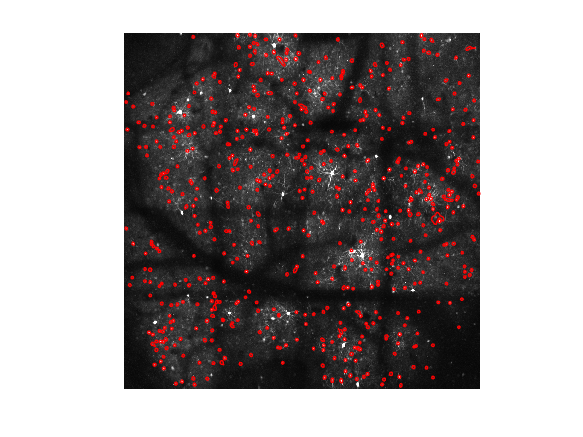


% Define the configuration to be used
config=[];
config = get_defaults(config);

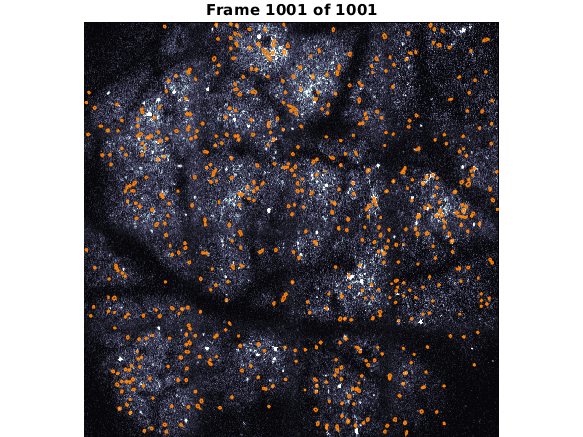

config.avg_cell_radius=7;


% If you do not have a native NVIDIA GPU, MATLAB may throw an error. 
if gpuDeviceCount("available")==0 || gpuDevice().DeviceSupported==0
   config.use_gpu=0;
end

% Decide the number of partitions based on available RAM and GPU memory. Typically, for a system with <=24 GB RAM, upto 10 x and y partitions would work. 
config.num_partitions_x=8;
config.num_partitions_y=8;


% Play with internal threshold parameters
config.thresholds.T_min_snr=4;
config.thresholds.spatial_corrupt_thresh=1.5;
config.cellfind_min_snr=0;


output=extractor(M,config);

17-Dec-2021 15:35:59: Getting GPU information... 
	 	 	 GPU Device 1 - GeForce GTX 1050 Ti: Available Memory: 3.4 Gb
	 	 	 - Selecting GPU device 1 
17-Dec-2021 15:36:00: Signal extraction on partition 64 (of 64):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1635 
	 	 	 	 minimum magnitude: 0.0324 
	 	 	 2 cells found after a total of 21 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 0 (2 removed) 
	 	 	 Zero cells, stopping. 
	 	 	 Providing non-negative traces. 
	 	 	 Count: 0 cells.
17-Dec-2021 15:37:25: Signal extraction on partition 63 (of 64):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise 

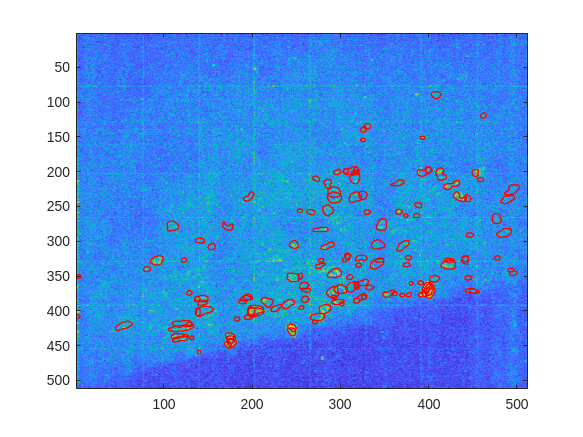

%% Check quality
figure;
%imagesc(output.info.max_image);
imagesc(output.info.summary_image)
plot_cells_overlay(output.spatial_weights,[1,0,0],[])